format long

## Task 1 prep

opts = detectImportOptions("C:\Users\mkhumalo2021\Downloads\TimeSeriesData\TimeSeriesData\BD+55_441.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
preview("C:\Users\mkhumalo2021\Downloads\TimeSeriesData\TimeSeriesData\BD+55_441.txt",opts)

ans = 8×6 table
      B_time        B_flux       R_time        R_flux       V_time        V_flux 
    ___________    ________    ___________    ________    ___________    ________

     58732.6843    3.497996    58732.68459     1.96183    58732.68445    2.352058
     58732.6843    3.497996    58732.68504    1.942857     58732.6849    2.360458
    58732.68475    3.487289    58732.68549    1.947021    58732.68535    2.329957
     58732.6852    3.450942    58732.68594    1.930594     58732.6858    2.344889
    58732.68565    3.497567    58732.68639    1.942537    58732.68625    2.361048
     58732.6861    3.461555    58732.68684    1.935141    58732.68669    2.333341
    58732.68655    3.431248    58732.68729     1.93129    58732.68714    2.331904
      58732.687    3.455091    58732.6877

BD55_441 = readmatrix("C:\Users\mkhumalo2021\Downloads\TimeSeriesData\TimeSeriesData\BD+55_441.txt",opts);
whos BD55_441

  Name            Size            Bytes  Class     Attributes

  BD55_441      101x6              4848  double              



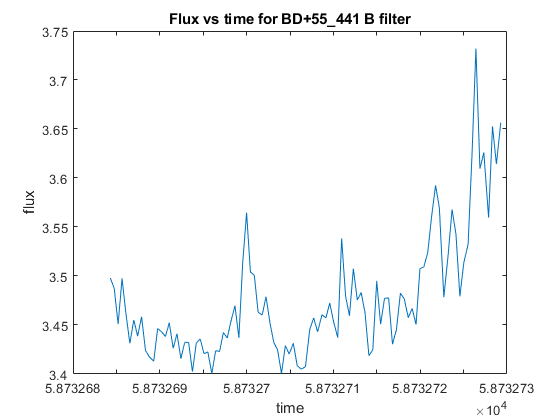

title('Flux vs time for BD+55\_441 B filter');
xlabel('time');
ylabel('flux');

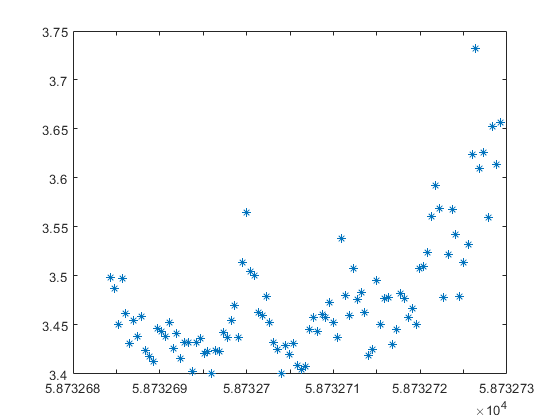

plot(BD55_441(:,1),BD55_441(:,2),'*')

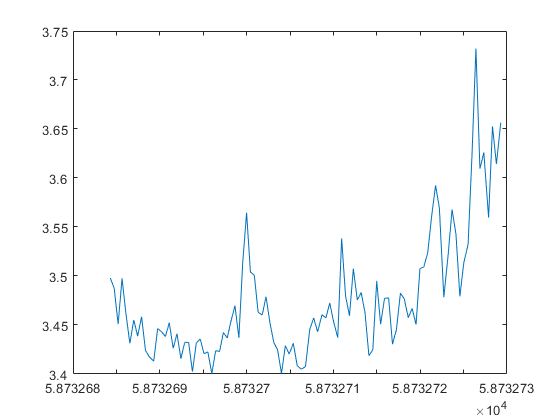

plot(BD55_441(:,1),BD55_441(:,2))

r = abs([0; BD55_441(:,1)] - [BD55_441(:,1);0])

r = 	1.0e+04 *

   5.873268430000000
                   0
   0.000000045000000
   0.000000045000000
   0.000000045000000
   0.000000045000000
   0.000000045000000
   0.000000045000000
   0.000000045000000
   0.000000045000000


round(mean(r(2:end-1)),8)

ans =      4.498000000000000e-04


round(std(r(2:end-1)),8)

ans =      4.915000000000000e-05
